clear
% Załadowanie zmiennych wyliczonych w poprzednich krokach
load("idenyfikacja_silnika_zmienne.mat")
load("idenyfikacja_ciagu_zmienne.mat")
load("identyfikacja_wahania_zmienne.mat", "theta_opt")

% warunki początkowe [pitch, ?, ?]
% UWAGA ZMIENIŁO SIE ALPHA_0 z 0.2ileś na 0.186
x0 = [0.186; 0; 0]

x0 =     0.1860
         0
         0


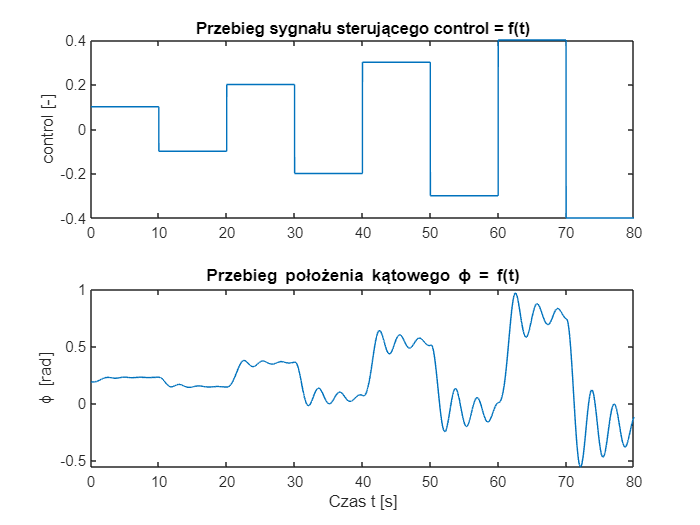

% Generowanie sygnalu prostokatnego z rosnaca amplituda, za pomoca bloczka signal builder 
t = [0 1 1 2 2 3 3 4 4 5 5 6 6 7 7 8] .*10;
y = [1  1 -1 -1 2 2 -2 -2 3 3 -3 -3 4 4 -4 -4] .*0.1;
%input = silnik.signals(1).values;
%pitch = silnik.signals(2).values;
%rpm = silnik.signals(3).values;
%time = silnik.time;
%save("przebieg_dynamiczny_pochylenia_prost_naras.mat", "time", "pitch", "rpm", "input")
load("przebieg_dynamiczny_pochylenia_prost_naras.mat")

% Zarejestrowany przebieg odpowiedzi układu na zadane sterowanie
% Sterowanie ograniczono do +/- 0.4
figure
subplot(2, 1, 1);
plot(time, input);
title("Przebieg sygnału sterującego control = f(t)");
ylabel("control [-]")
subplot(2, 1 , 2);
plot(time, pitch);
title("Przebieg położenia kątowego \phi = f(t)");
xlabel("Czas t [s]")
ylabel("\phi [rad]")

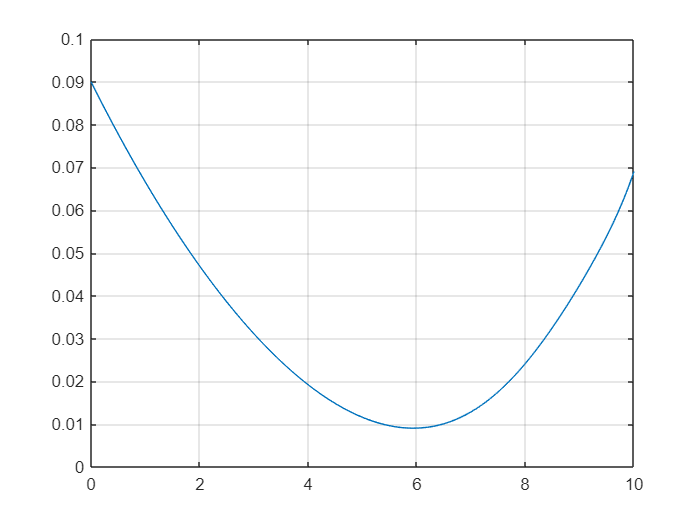

% Wyznaczenie optymalnej wartosci kp z równania ... + kp * (F(x2))
m_vec = [];
kp = 0:.1:10;
% Wyliczanie wspolczynnikow dla roznych wartosci kp metoda rk4
for KP = kp
    [~, x] = rk4_pochylenie(input, x0, 80, size(input, 1) - 1, theta_opt, KP, K_opt, H, F);
    m = mean((pitch - x(:, 1)).^2); % sprawdzanie dopasowania metoda najmniejszych kwadratow
    m_vec = [m_vec, m];
end

figure
plot(kp, m_vec); grid on;

% Optymalna wartosc kp_opt 
[~, i] = min(m_vec);
kp_opt = kp(i)

kp_opt = 5.9000

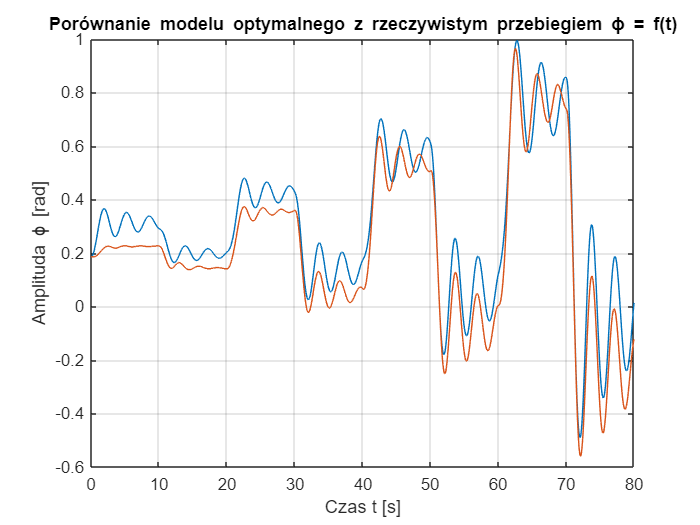

[time, x] = rk4_pochylenie(input, x0, 80, size(input, 1) - 1, theta_opt, kp_opt, K_opt, H, F);

figure
plot(time, x(:, 1), time, pitch); grid on
xlim([0 80])
title("Porównanie modelu optymalnego z rzeczywistym przebiegiem \phi = f(t)")
xlabel("Czas t [s]")
ylabel("Amplituda \phi [rad]")

% Generowanie przebiegu piłokształtnego narastającego 
t = [0 1 1 2 2 3 3 4 4 5 5 6 6 7 7 8] .*10;
y = [0 1 0 -1 0 2 0 -2 0 3 0 -3 0 4 0 -4] .*.1;
%input = silnik.signals(1).values;
%pitch = silnik.signals(2).values;
%rpm = silnik.signals(3).values;
%time = silnik.time;
%save("przebieg_dynamiczny_pochylenia_piłoz_naras.mat", "time", "pitch", "rpm", "input")
%load("przebieg_dynamiczny_pochylenia_piłoz_naras.mat")

% Zarejestrowany przebieg odpowiedzi układu na zadane sterowanie
% Sterowanie ograniczono do +/- 0.4
figure
subplot(2, 1, 1);
plot(time, input);
title("Przebieg sygnału sterującego control = f(t)");
ylabel("control [-]")
subplot(2, 1 , 2);
plot(time, pitch);
title("Przebieg położenia kątowego \phi = f(t)");
xlabel("Czas t [s]")
ylabel("\phi [rad]")


% TODO zrobic wyznaczenie optymalnego kp dla powyzszego przebiegu i moze jeszcze dla jednego
% ALE NA PEWNO JESZCZE RAZ ALPHA ZERO OGARNAC

% Zapis optymalnych współczynników do pliku 
save("identyfikacja_pochylenie.mat", "kp_opt", "theta_opt", "K_opt", "H", "F")